## Jesus Molina Roldan

oli =[57.52	45.27	14.14	6.58	5.68	5.09	3.34	2.97	26.17;
    57.9	47.73	14.11	7.21	5.37	5.06	3.29	2.65	27.04;
    59.38	52.09	15.02	7	5.41	4.36	3.24	2.81	28.27;
    61.6	53.29	16.33	7.42	5.55	4.34	3.09	2.74	28.9;
    66.99	54.56	17.42	8.09	5.73	5.05	3.4	2.81	28.86;
    73.06	54.92	18.2	8.65	5.94	4.99	3.54	2.92	28.16;
    71.48	55.46	19.33	8.56	6.12	5.08	3.65	2.97	27.62]

oli =      5.752000000000000e+01     4.527000000000000e+01     1.414000000000000e+01     6.580000000000000e+00     5.680000000000000e+00     5.090000000000000e+00     3.340000000000000e+00     2.970000000000000e+00     2.617000000000000e+01
     5.790000000000000e+01     4.773000000000000e+01     1.411000000000000e+01     7.210000000000000e+00     5.370000000000000e+00     5.060000000000000e+00     3.290000000000000e+00     2.650000000000000e+00     2.704000000000000e+01
     5.938000000000000e+01     5.209000000000000e+01     1.502000000000000e+01     7.000000000000000e+00     5.410000000000000e+00     4.360000000000000e+00     3.240000000000000e+00     2.810000000000000e+00     2.827000000000000e+01
     6.160000000000000e+01     5.329000000000000e+01     1.633000000000000e+01     7.420000000000000e+00     5.550000000000000e+00     4.340000000000000e+00     3.090000000000000e+00     2.740000000000000e+00     2.890000000000000e+01
     6.698999999999999e+01     5.456000000000000e+01  

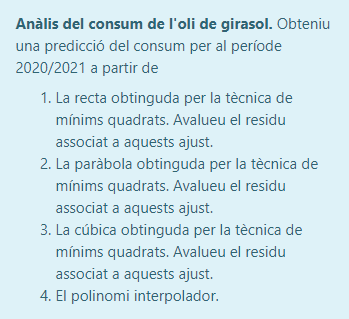

oli_aux = sum(oli,2)'

oli_aux =      1.667600000000000e+02     1.703600000000000e+02     1.775800000000000e+02     1.832600000000000e+02     1.929100000000000e+02     2.003800000000000e+02     2.002700000000000e+02


indices = 1:length(oli_aux)

indices =      1     2     3     4     5     6     7


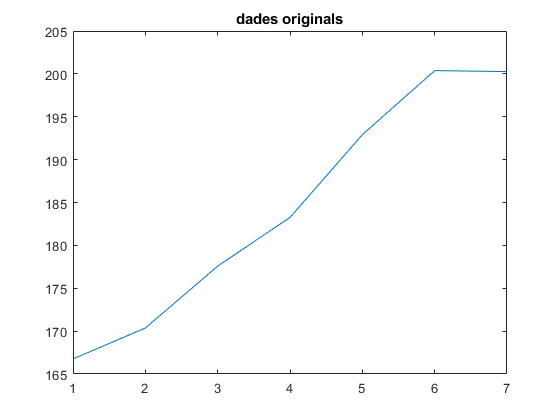

plot(indices,oli_aux)
title('dades originals')

**1.Recta**

p = polinomio_interpolador_minimos_cuadrados(indices, oli_aux, 1);
polyval(p,length(oli_aux)+1)

ans =      2.096314285714286e+02


**2.Parabola**

p = polinomio_interpolador_minimos_cuadrados(indices, oli_aux, 2);
polyval(p,length(oli_aux)+1)

ans =      2.082942857142862e+02


**3.Cúbica**

p = polinomio_interpolador_minimos_cuadrados(indices, oli_aux, 3);
polyval(p,length(oli_aux)+1)

ans =      1.964542857142864e+02


4. Polinomi interpolador

grau = length(oli_aux)-1;
p = polyfit(indices,oli_aux,grau);
polyval(p,length(oli_aux)+1)

ans =      2.350800000000009e+02


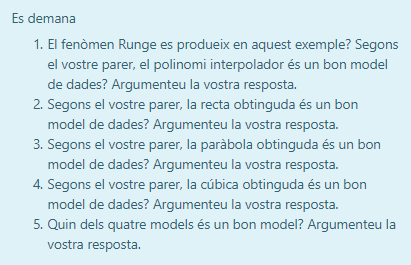

oli_aux = sum(oli,2)';
indices = 1:length(oli_aux)

indices =      1     2     3     4     5     6     7


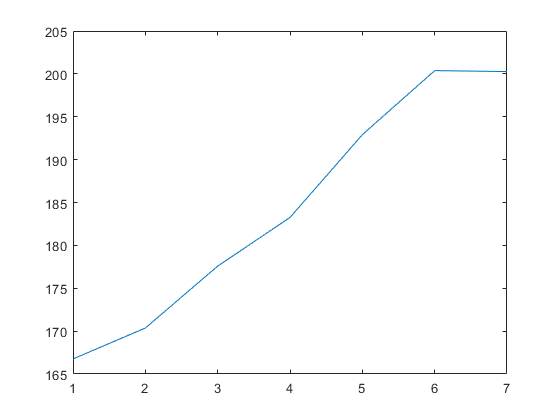

plot(indices,oli_aux)

**1.Recta**

Como podemos observar no es un buen modelo da mucho error.

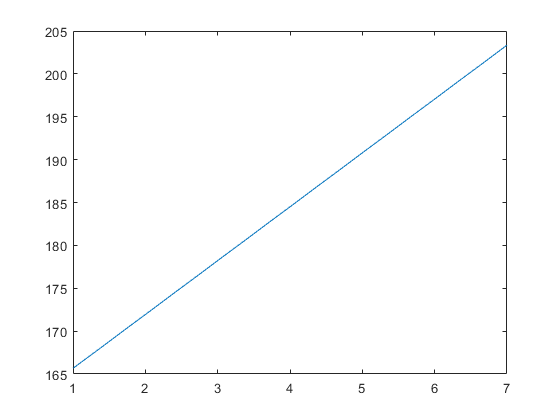

p = polinomio_interpolador_minimos_cuadrados(indices, oli_aux, 1);
x = 1:length(oli_aux);
y = polyval(p,x);
plot(x,y)

sum(error_absoluto(oli_aux, y))

ans =      1.308285714285711e+01


**2.Parabola**

Como podemos observar no es un buen modelo da mucho error.

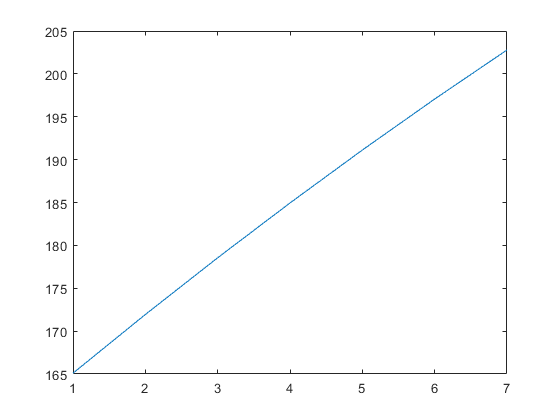

p = polinomio_interpolador_minimos_cuadrados(indices, oli_aux, 2);
x = 1:length(oli_aux);
y = polyval(p,x);
plot(x,y)

sum(error_absoluto(oli_aux, y))

ans =      1.352857142857127e+01


**3.Cúbica**

Como podemos observar no es un buen modelo da mucho error. Si nos fijamos cada vez que augmentamos el grado nos va dando mejor resultado.

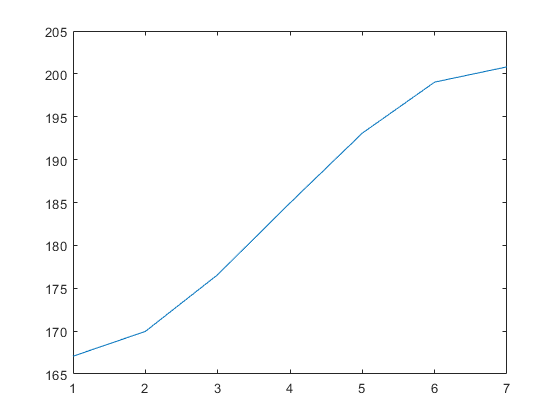

p = polinomio_interpolador_minimos_cuadrados(indices, oli_aux, 3);
x = 1:length(oli_aux);
y = polyval(p,x);
plot(x,y)

sum(error_absoluto(oli_aux, y))

ans =      5.465238095237453e+00


**4. Polinomi interpolador**

Este es con diferencia el que mejor resultado da. No se produce el fenomeno de la Runge ya que si vemos la grafica en los extremos no hay oscilaciones.

grau = length(oli_aux)-1;
p = polyfit(indices,oli_aux,grau);
x = 1:length(oli_aux);
y = polyval(p,x);
plot(x,y)

sum(error_absoluto(oli_aux, y))

ans =      6.053824108676054e-12


function [error_absoluto] = error_absoluto(valor_exacto, valor_aproximado)
    error_absoluto = abs(valor_exacto-valor_aproximado);
end
function [coeficientes] = polinomio_interpolador_minimos_cuadrados(x, y, grado)
    A = ones(length(x),grado+1);
    i = grado;
    while(i  > 0)
        A(:,((grado+1)-i)) = (x').^i;
        i = i-1;
    end
    b = y';
    coeficientes  = minimos_cuadrados(A,b)';
end
function [x] = minimos_cuadrados(A,b)
    %A'*Ax=A'b
    C = A'*A;
    d = A'*b;
    x = C\d;
end